`Name: Maria Sabouri Dodaran`

`Student Number: 401248049`

# ***Question 1***

- Define paremeters

- Generate the Discrete-Time signal

Fs = 8000;      
f1 = 440;       
f2 = 1200;      
T  = 0.1;       

N = Fs*T;       
n = 0:N-1;     
t = n/Fs;       

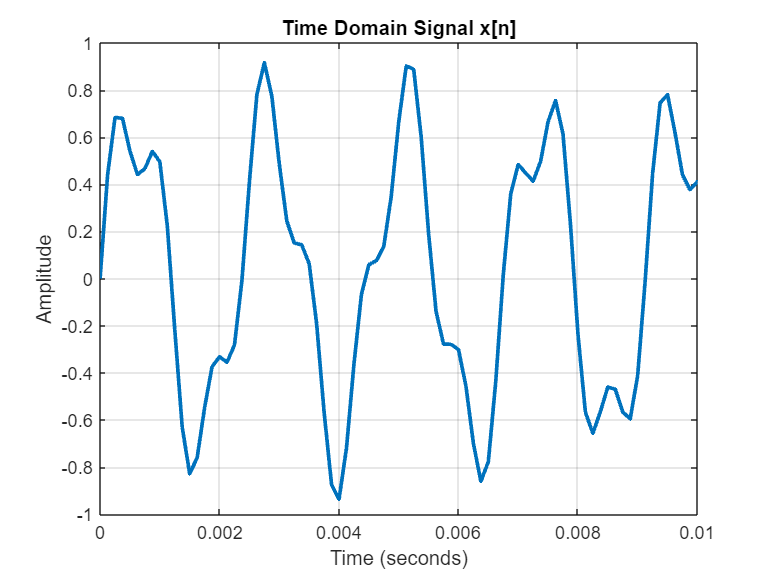

x = 0.7*sin(2*pi*f1*n/Fs) + 0.25*sin(2*pi*f2*n/Fs);

figure;
plot(t, x, 'LineWidth', 2);
xlim([0 0.01])
grid on;
xlabel("Time (seconds)");
ylabel("Amplitude");
title("Time Domain Signal x[n]");

## **Part a**

Uniform scalar quantizers are of two types: **midrise** and **midtread**. A midrise quantizer is used with an even number of output levels, and a **midtread** quantizer with an odd number. The **midrise** quantizer has a partition interval that brackets zero.

For the special case $\Delta$= 1, we can simply compute the output values for these quantizers as:

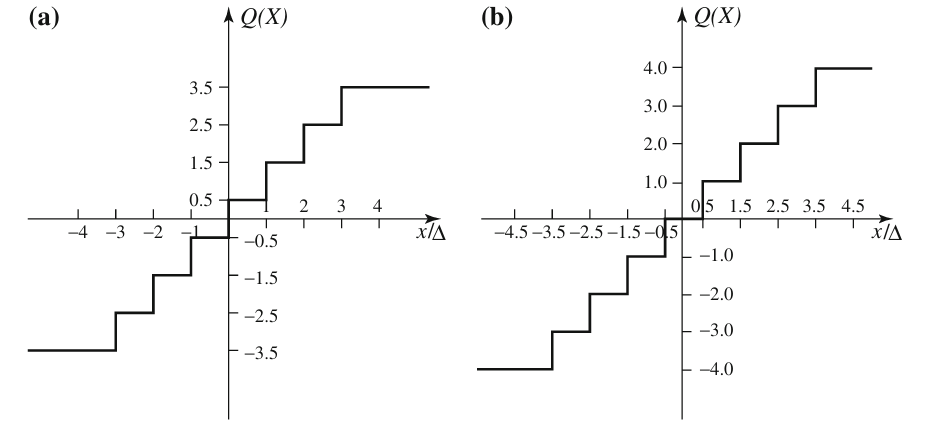

Uniform scalar quantizers:** a** midrise; **b** midtread.

Suppose the input is uniformly distributed in the interval **[−Xmax, Xmax]**. **M **is levelquantizer. The step size $\Delta$ is given by:


$$\Delta =\frac{2\;X_{\max } }{M}$$


Decision boundaries bi for a midrise quantizer are **[(i − 1)**$\Delta$**, i**$\Delta$**], i = 1.. M/2**, covering positive data X (and another half for negative X values). Output values yi are the midpoints **i**$\Delta$**−**$\Delta$**/2,i = 1..M/2**,again just considering positive data.

Xmax = max(x);
% Xmin = -Xmax;
Xmin = min(x)

Xmin = -0.9414

M = 4  |  Delta = 0.470691  |  MSE (D_gran) = 0.0205038156


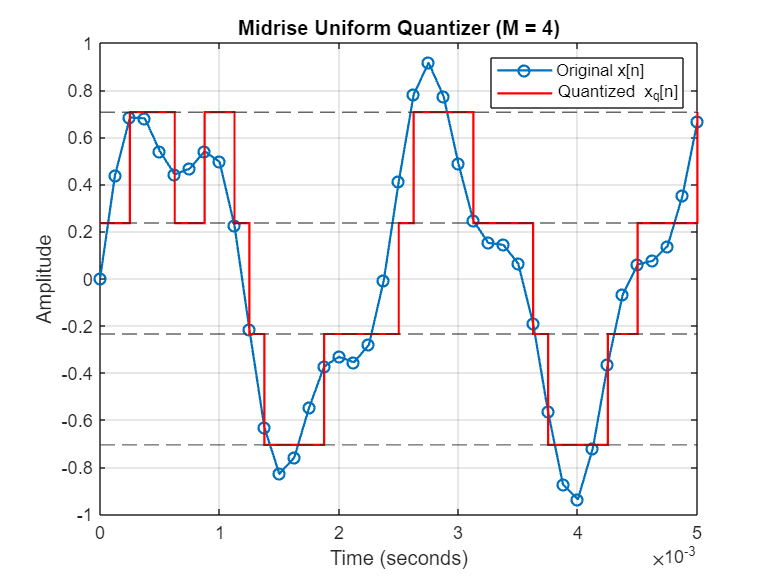

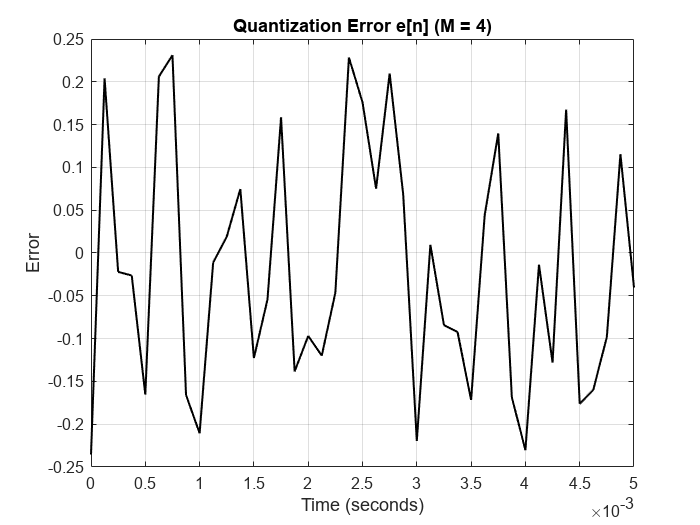

M = 8  |  Delta = 0.235345  |  MSE (D_gran) = 0.0051938816


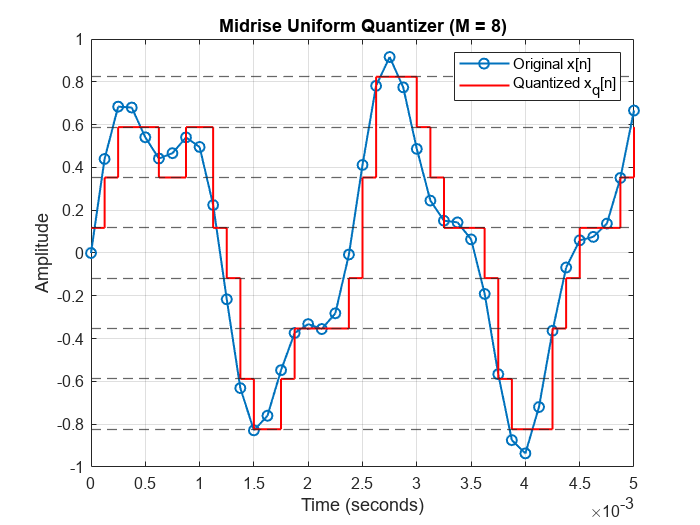

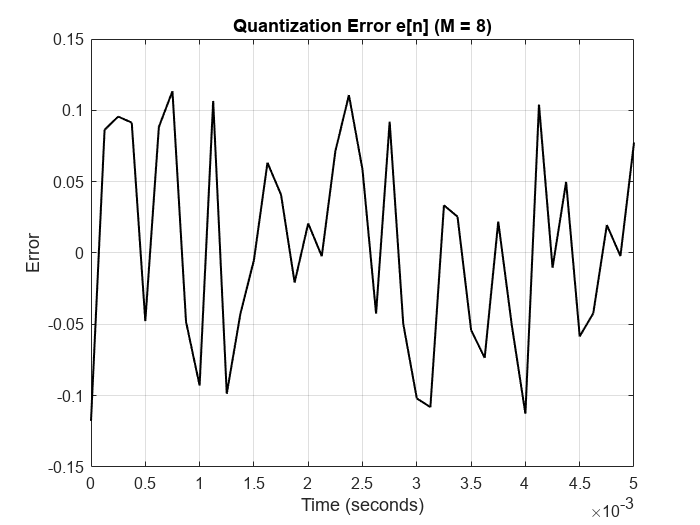

M = 16  |  Delta = 0.117673  |  MSE (D_gran) = 0.0011880020


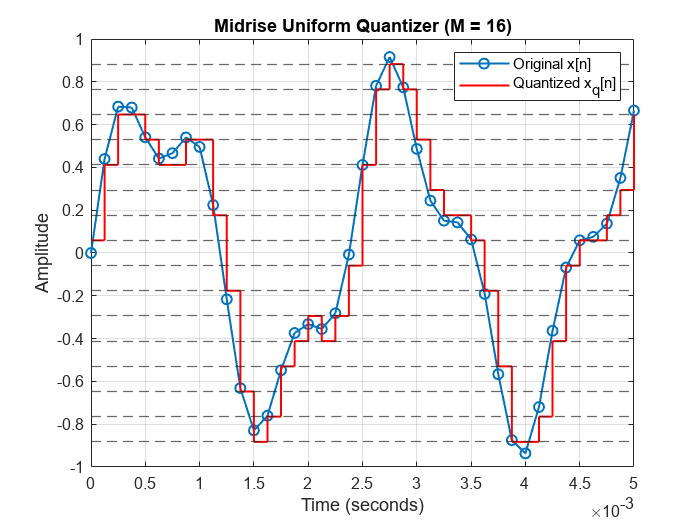

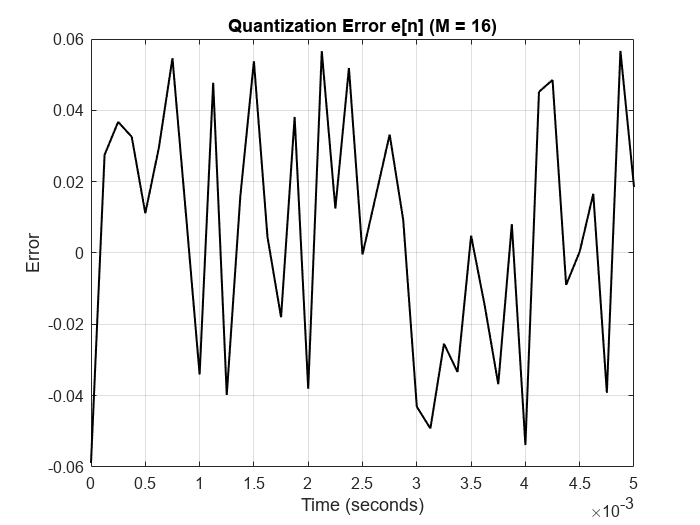


M_list = [4 8 16];

for idx = 1:length(M_list)

    M = M_list(idx);

    Delta = (Xmax - Xmin)/M;    

    xq = zeros(size(x));

    for k = 1:length(x)
        if x(k) >= 0
            i = floor(x(k)/Delta) + 1;
            if i > M/2
                i = M/2;
            end
            xq(k) = (i - 0.5)*Delta;
        else
            i = floor(-1 * x(k)/Delta) + 1;
            if i > M/2
                i = M/2;
            end
            xq(k) = -1 * ((i - 0.5)*Delta);
        end

    end

    e = x - xq;

    D_gran = mean(e.^2);
    fprintf("M = %d  |  Delta = %.6f  |  MSE (D_gran) = %.10f\n", ...
            M, Delta, D_gran);

    levels = ( (-1*M/2 + 1:M/2) - 0.5 ) * Delta;

    figure;
    plot(t, x,'-o', 'LineWidth', 1.2);
    hold on;
    stairs(t, xq, 'r', 'LineWidth', 1.2);
    for lev = 1:length(levels)
        yline(levels(lev), '--', 'LineWidth', 0.8);
    end
    grid on;

    title(['Midrise Uniform Quantizer (M = ', num2str(M), ')']);
    xlabel('Time (seconds)');
    ylabel('Amplitude');
    xlim([0 0.005]);
    legend('Original x[n]', 'Quantized x_q[n]');

    figure;
    plot(t, e, 'k', 'LineWidth', 1.2);
    grid on;

    title(['Quantization Error e[n] (M = ', num2str(M), ')']);
    xlabel('Time (seconds)');
    ylabel('Error');
    xlim([0 0.005]);

end

The rate of the quantizer is


$$R=\left\lceil \log_2 M\right\rceil$$


Increasing the number of quantization levels M reduces the step size Δ, which decreases the mean squared error (granular distortion) of the signal. This improves the fidelity of the quantized signal and increases the signal-to-quantization-noise ratio (SQNR). However, it also requires more bits per sample, increasing storage or transmission cost. Therefore, designing a uniform quantizer involves a trade-off between **quantization accuracy** and **bit rate**.

**Refrences:**

[**.\extracted_FoM.pdf**](matlab:open('.\extracted_FoM.pdf'))

## **Part b**

In fixed-point representation, a number is stored using a limited number of bits. 

**WL (Word Length)** = total number of bits used to store the number.

**FL (Fraction Length)** = number of bits used for the fractional part (after the binary point). FL controls precision.

The number of integer bits is:

Integer bits = WL − FL

So any values are in range:


$$\left\lbrack \frac{2^{\textrm{WL}-1} -1}{2^{\textrm{FL}} },-\frac{2^{\textrm{WL}-1} }{2^{\textrm{FL}} }\right\rbrack$$


So larger FL → smaller step → more precision → less quantization noise

WL = 8, FL = 4  -->  MSE = 0.000324474132


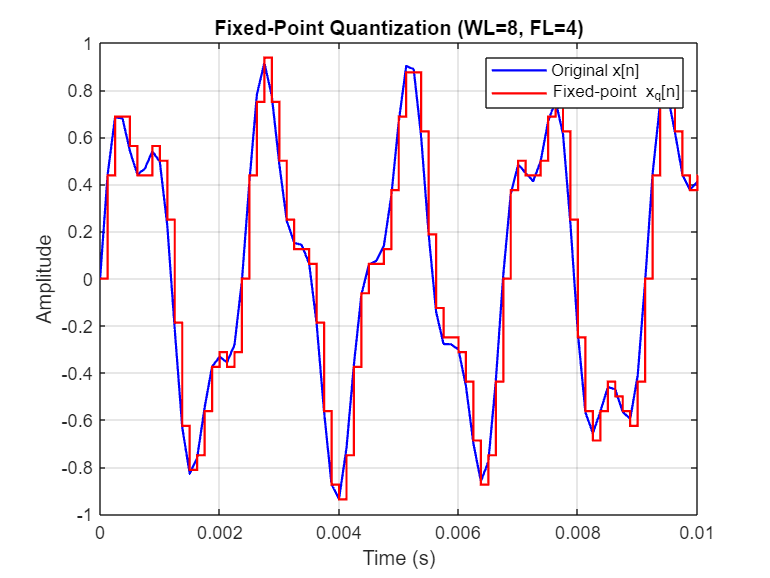

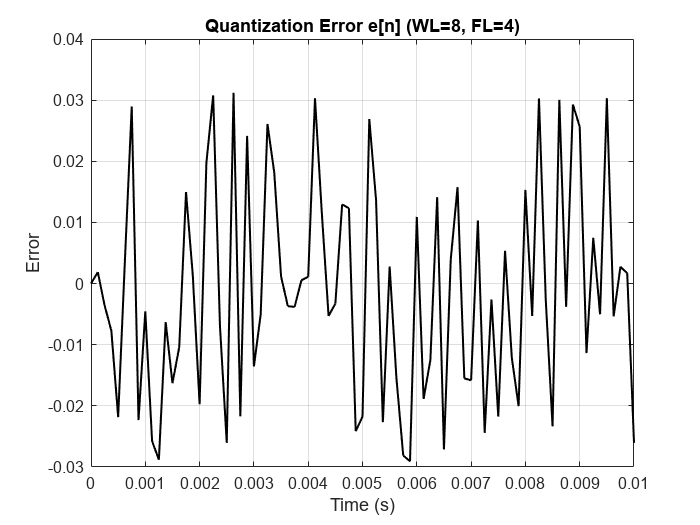

WL = 8, FL = 6  -->  MSE = 0.000018946256


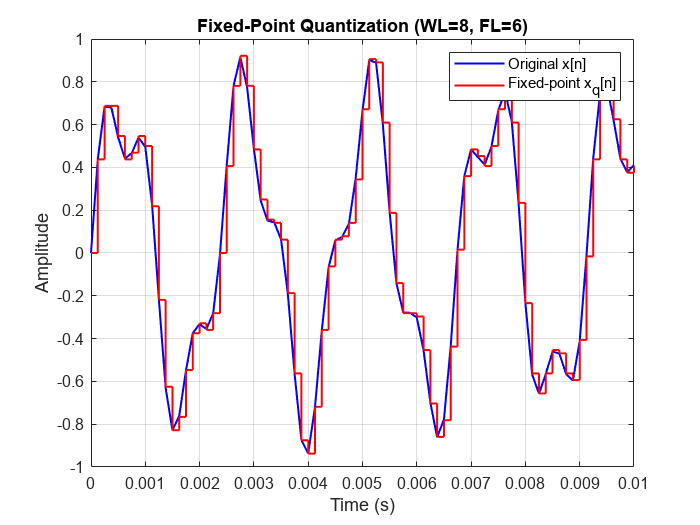

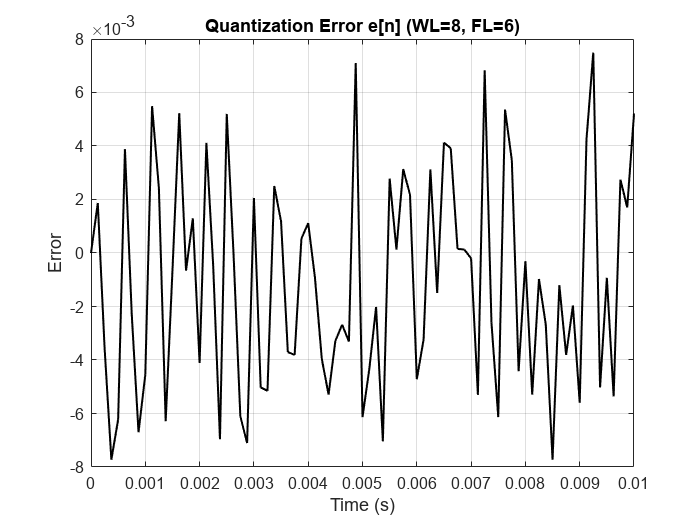

WL = 8, FL = 7  -->  MSE = 0.000005584087


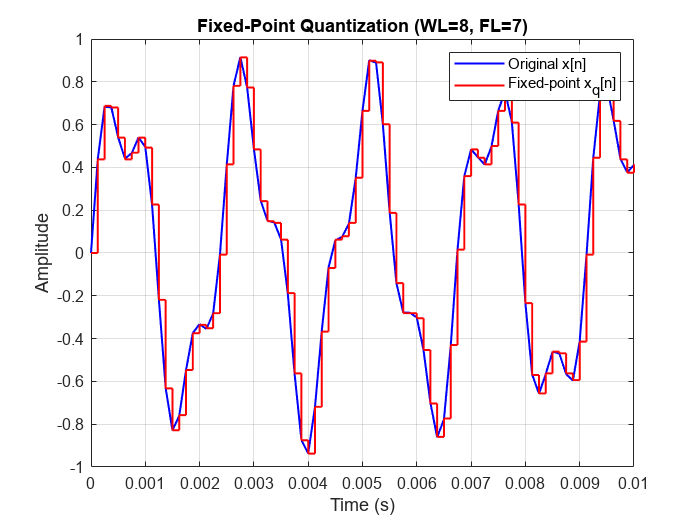

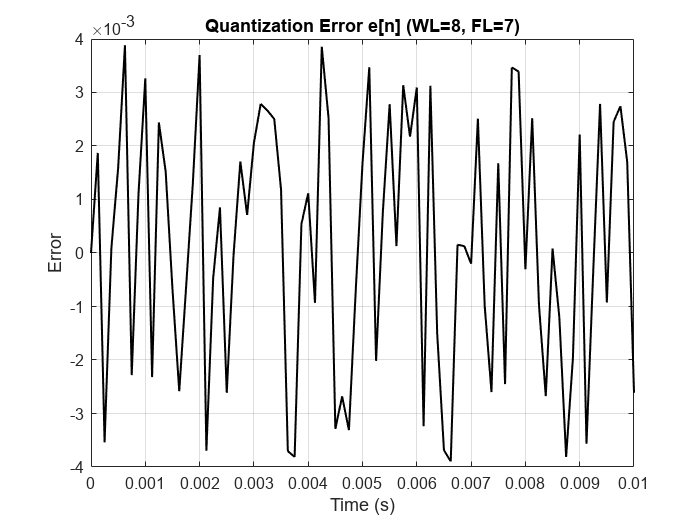

WL = 16, FL = 10  -->  MSE = 0.000000083658


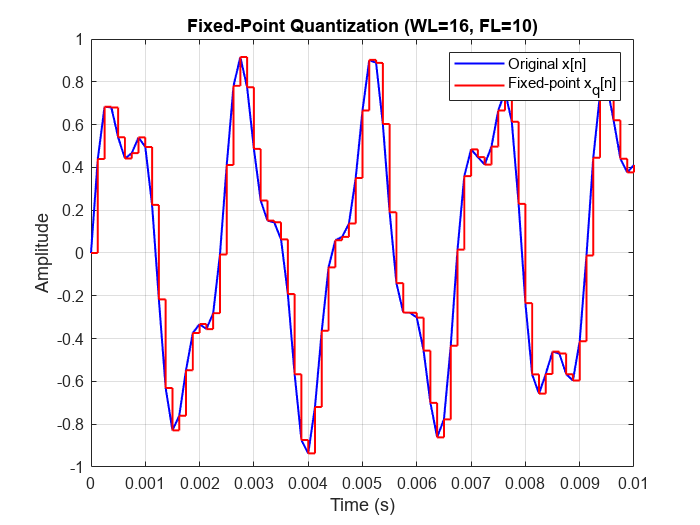

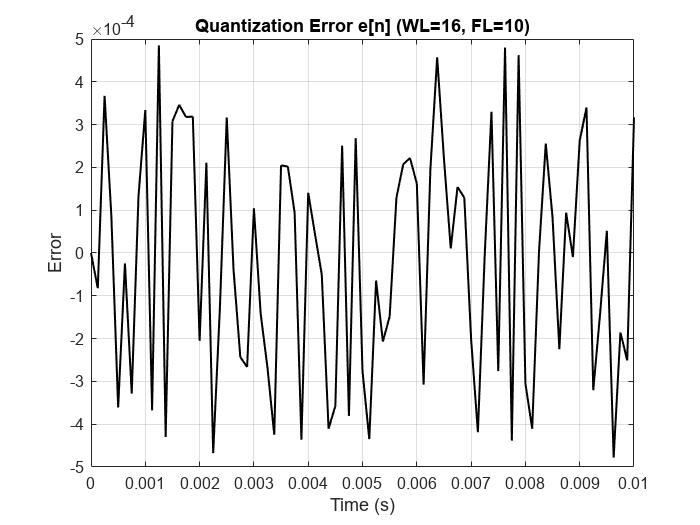

WL = 16, FL = 12  -->  MSE = 0.000000004857


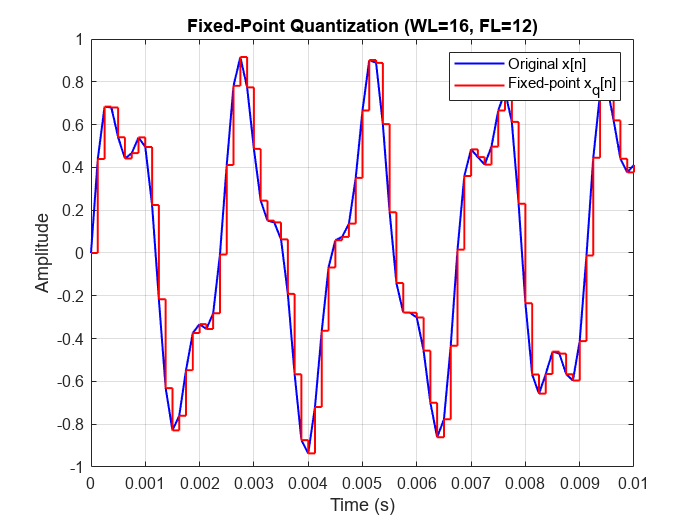

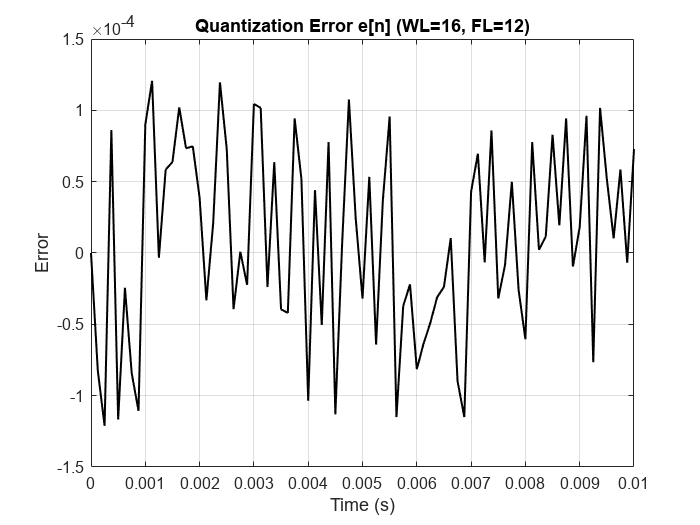

WL = 16, FL = 14  -->  MSE = 0.000000000312


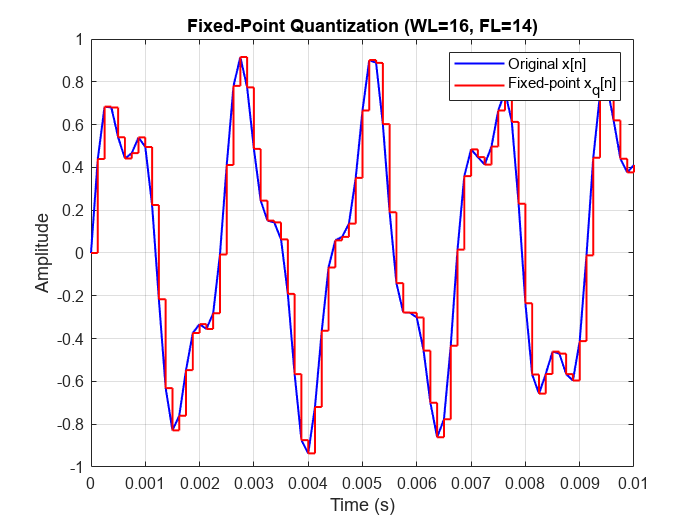

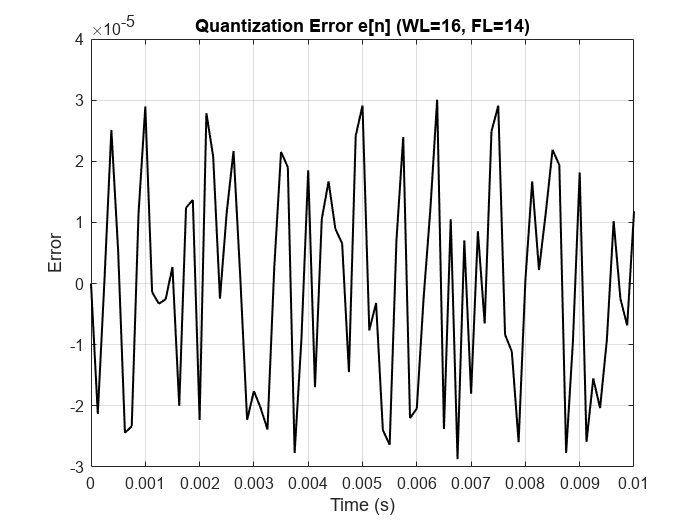

WL_list = [8 16];

FL_list_8  = [4 6 7];
FL_list_16 = [10 12 14];

for w = 1:length(WL_list)

    WL = WL_list(w);

    if WL == 8
        FL_list = FL_list_8;
    else
        FL_list = FL_list_16;
    end

    for f = 1:length(FL_list)

        FL = FL_list(f);

        F = fimath( ...
            'RoundingMethod', 'Nearest', ...
            'OverflowAction', 'Saturate');

        % fi(value, signed, wordlength, fractionlength)
        x_fixed = fi(x, 1, WL, FL, 'fimath', F);

        xq = double(x_fixed);

        e = x - xq;

        MSE = mean(e.^2);

        fprintf("WL = %d, FL = %d  -->  MSE = %.12f\n", WL, FL, MSE);

        figure;
        plot(t, x, 'b', 'LineWidth', 1.2);
        hold on;
        stairs(t, xq, 'r', 'LineWidth', 1.2);
        grid on;

        title(['Fixed-Point Quantization (WL=', num2str(WL), ', FL=', num2str(FL), ')']);
        xlabel('Time (s)');
        ylabel('Amplitude');
        legend('Original x[n]', 'Fixed-point x_q[n]');
        xlim([0 0.01]);

        figure;
        plot(t, e, 'k', 'LineWidth', 1.2);
        grid on;

        title(['Quantization Error e[n] (WL=', num2str(WL), ', FL=', num2str(FL), ')']);
        xlabel('Time (s)');
        ylabel('Error');
        xlim([0 0.01]);

    end
end

 When FL increases:

- step size decreases

- quantization noise decreases

- MSE becomes smaller

When WL-FL is small:

- integer bits become small

- overflow becomes more likely

- distortion becomes large (MSE increases suddenly)

**Refrences:**

[https://www.mathworks.com/help/fixedpoint/ref/embedded.fi.html#mw_0c68b715-53e7-4709-8537-85c1216e755e](https://www.mathworks.com/help/fixedpoint/ref/embedded.fi.html#mw_0c68b715-53e7-4709-8537-85c1216e755e)

[https://www.mathworks.com/help/fixedpoint/ref/embedded.fimath.html](https://www.mathworks.com/help/fixedpoint/ref/embedded.fimath.html)